# 4BM00-Assingment 4

[https://nl.mathworks.com/help/images/morphological-filtering.html](https://nl.mathworks.com/help/images/morphological-filtering.html)

- Load 1 image and find a suitable threshold to transform grayscale image into black white image.

- Keypoint: find a way to identify edge with threshold analysis to targeted image file.

clc; clear all; clear figure; clear var
% df1=imread('Images\Image0001.tiff');
patern=load('Images\Labels.mat');pat=struct2table(patern);
% ex=patern.Labels;
dc = dir('Images\*.tiff');dct=struct2table(dc);
Image_table=[dct pat];%make table and concatenate the pattern tag.

%Image data store
ds = imageDatastore("Images\","FileExtensions",'.tiff');%read only tiff files
% ds_show=read(ds);
df1=imread(ds.Files{1}); %read 1 image file for example
% figure, imshow(imgw)

img=1; % for figure
df1=im2gray(df1); %gray image

Find image and turn into gray image matrix: **df1**

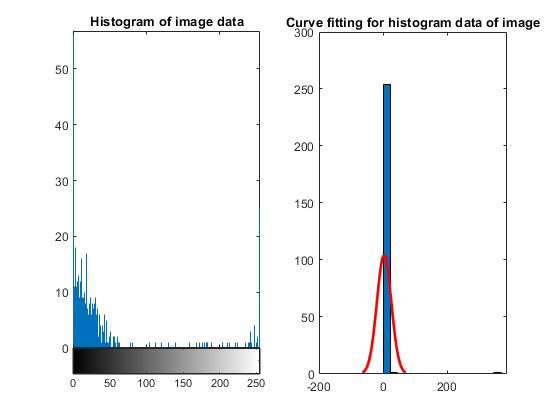

% histogram of image data
figure
figure(img)
%imhist(I) calculates the histogram for the grayscale image I. The imhist function returns the histogram counts in counts and the bin locations in binLocations.
subplot(1,2,1)
imhist(df1)
title('Histogram of image data')
imh1=imhist(df1);
% Do curve fitting (histfit) to the histogram line, thus we can substract edge value of the histogram
subplot(1,2,2)
hift1=histfit(imh1);
title('Curve fitting for histogram data of image')

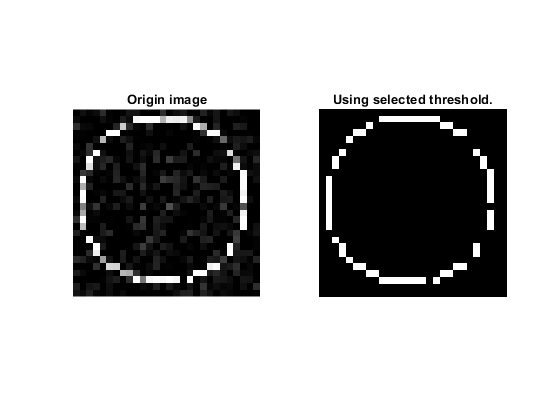


%from the histogram, the best threshoold can be taken:
hift1_max=max(hift1(2).YData); %substract line data only, and taking the maximum value

%Use selecting threshold and use as image filter
figure
figure(img+1)
% [valeyvalue, valyindex]=findpeaks(-imh1)
% figure
% % level = graythresh(df1)
% % df_bw = imbinarize(df1,level);
% figure(img+2)
threshold=hift1_max;
df_bw =df1 > threshold;
subplot(1,2,1)
imshow(df1)
title('Origin image')
subplot(1,2,2)
imshow(df_bw)
title('Using selected threshold.')

% exportgraphics(figure(img+1),'Q1_result.jpg',"Resolution",150)

2. Calculate Hough transform to find the longest line in the mage.

https://nl.mathworks.com/help/images/ref/imopen.html

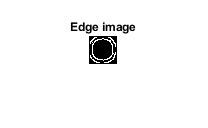

%extract edge of the image
edf1=edge(df1,'canny');
figure
figure(img+2)
imshow(edf1)
title('Edge image')

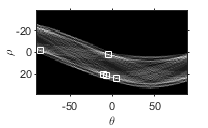


[H,T,R]=hough(edf1);
imshow(H,[],'XData',T,'YData',R,...
            'InitialMagnification','fit');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal, hold on;

% Find peaks 
P  = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))));
x = T(P(:,2)); y = R(P(:,1));
plot(x,y,'s','color','white');

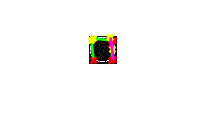



lines = houghlines(edf1,T,R,P,'FillGap',5,'MinLength',2);
figure, figure(img+3),imshow(df1), hold on
% 
% imshow(df1)
max_len = 0;
for k = 1:length(lines)
   xy = [lines(k).point1; lines(k).point2];
   plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');

   % Plot beginnings and ends of lines
   plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
   plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');

   % Determine the endpoints of the longest line segment
   len = norm(lines(k).point1 - lines(k).point2);
   if ( len > max_len)
      max_len = len;
      xy_long = xy;
   end
end

plot(xy_long(:,1),xy_long(:,2),'LineWidth',2,'Color','#FF00FF');
hold on


fprintf('Longest length');

Longest length

disp(len)

   22.2036



3. To �find the area of the shape use morphological operators, and come to pixel number = area of the shape.